% (1) simulate threshold and intensity data
% (2) fit models back


## making threshold ground truth

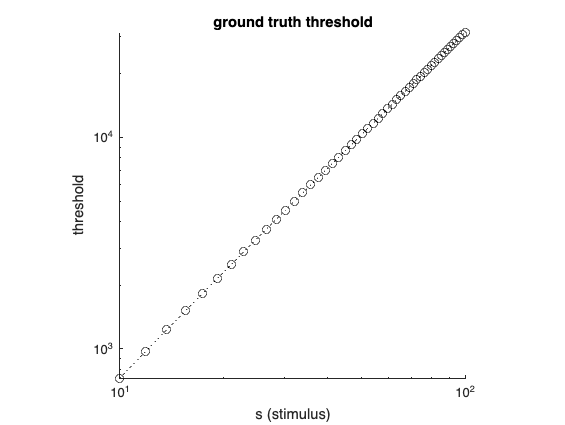

% threshold function

mk_threshold = @(s, w, d, beta) ((s + d).^beta)./w;

w = 0.05;
s = linspace(10, 100, 50);
d = -0.54;
beta = 1.6;

threshold = mk_threshold(s, w, d, beta);

figure (1), clf
loglog(s, threshold, 'ko:')
xlabel('s (stimulus)'), ylabel('threshold'), box off, axis square
title('ground truth threshold')

## making intensity ground truth

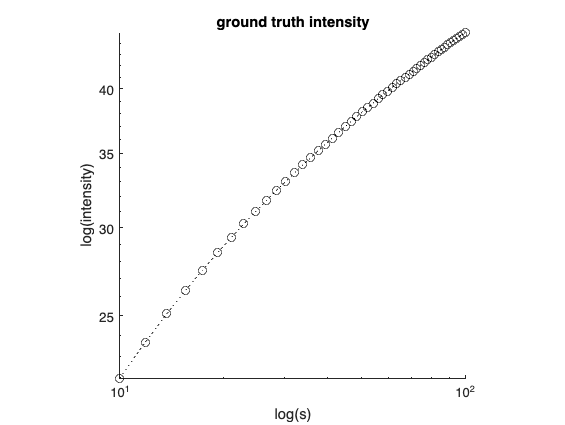

% Here, I use a log function to generate intensity data

mk_intensity = @(s, p1) log(s .* p1);% p2 * s.^p1; %log(s .* .9);

p1 = .9;
%p2 = 0.5;

intensity = 10 .* mk_intensity(s, p1);

figure (2), clf
loglog(s, intensity, 'ko:'), axis square
title('ground truth intensity'), xlabel('log(s)'), ylabel('log(intensity)'), box off

## generate threshold and intensity data

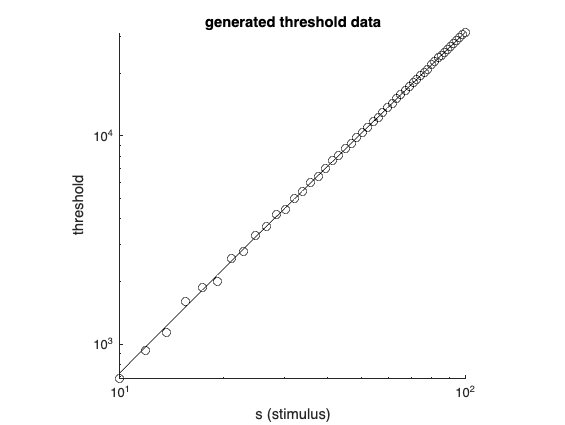

f = [];

f.thresh_dt = threshold + normrnd(0, 70, size(s));
f.intensity_dt = intensity + normrnd(0, .5, size(s));

figure (3), clf,
loglog(s, f.thresh_dt, 'ko'), hold on
loglog(s, threshold, 'k-')
xlabel('s (stimulus)'), ylabel('threshold'), box off, axis square
title('generated threshold data')

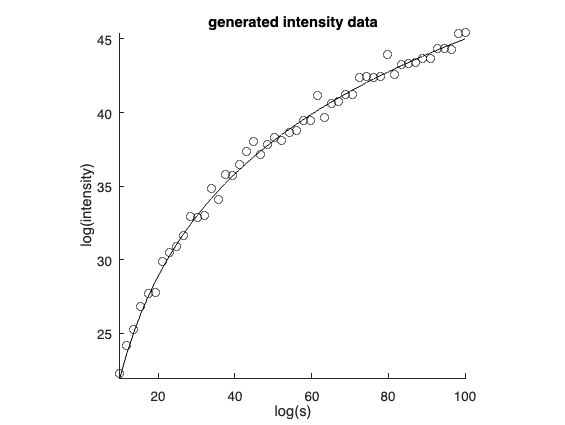


figure (4), clf
plot(s, f.intensity_dt, 'ko'), hold on
loglog(s, intensity, 'k-'), axis square, box off
title('generated intensity data'), xlabel('log(s)'), ylabel('log(intensity)'), box off

## fit threshold data (First row of Figure 4)

% fitting function
loss_thresh = @(s, w, d, beta, dt) sum((log(mk_threshold(s, w, d, beta))- log(dt)).^2);

thresh_init = [1, 0.5, 1.5];

% fitting threshold data
f.thresh_prm = fminsearch(@(x) loss_thresh(s, x(1), x(2), x(3), f.thresh_dt), thresh_init);

% plot threshold fit
f.thresh_axis = linspace(min(s), max(s), 100);
f.thresh_prd  = mk_threshold(f.thresh_axis, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3));


## plot threshold data fit

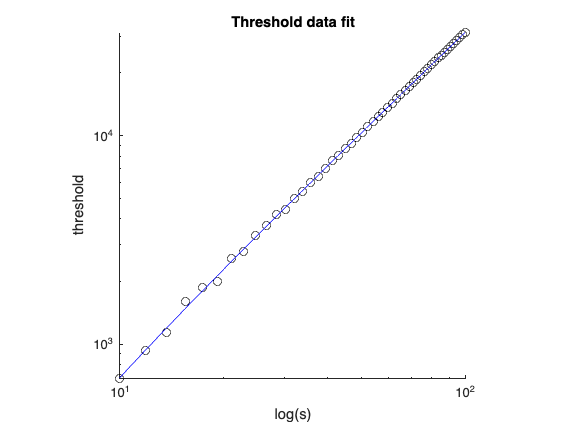

figure (1), clf
loglog(s, f.thresh_dt, 'ko'), hold on
loglog(f.thresh_axis, f.thresh_prd, 'b-')
title('Threshold data fit'), axis square, box off, 
xlabel('log(s)'), ylabel('threshold')

## make predictions to intensity data (row )

% preparations

n_repeats = 100;

## modulated Poisson model (full noise model)

loss1 = @(s, d, w, beta, c, g, sc, dt) sum((log(mkPercept(s, d, w, beta, c, g, sc)) - log(dt)).^2);

prm = []; prd = []; r2 = [];

for k = 1 : n_repeats
    init = rand(1, 3) * 10;

    prm(k, :)= fminsearch(@(x) loss1(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), x(1), x(2), x(3), f.intensity_dt), init);

    % make model prediction
    prd(k, :) = mkPercept(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), prm(k, 1), prm(k, 2), prm(k, 3));

    % compute r2
    r2(k) = compute_r2(f.intensity_dt, prd(k, :));
end

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.593102 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.709613 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.690994 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.578668 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.636756 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.591177 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase 

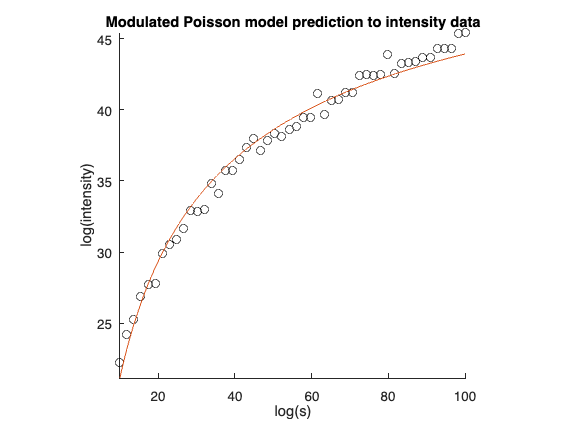


idx = find(r2 == max(r2));
f.perc_prm_fullmodel = prm(idx, :);
f.perc_prd_fullmodel = mkPercept(f.thresh_axis, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), f.perc_prm_fullmodel(1), f.perc_prm_fullmodel(2), f.perc_prm_fullmodel(3));

% visualize the model fit
figure (2), clf
plot(s, f.intensity_dt, 'ko'), hold on
plot(f.thresh_axis, f.perc_prd_fullmodel), axis square, box off
title('Modulated Poisson model prediction to intensity data')
xlabel('log(s)'), ylabel('log(intensity)')

## Additive model

loss2 = @(s, d, w, beta, sigma, c, sc, dt) sum((log(mkPercept_additive(s, d, w, beta, sigma, c, sc)) - log(dt)).^2);

prm = []; prd = []; r2 = [];

for k = 1 : n_repeats
    init = rand(1, 3) * 10;%[2, 50000, 20] +randn(1, 3);
    prm(k, :) = fminsearch(@(x) loss2(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), x(1), x(2), x(3), f.intensity_dt), init);

    % make model predictions
    prd(k, :) = mkPercept_additive(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), prm(1), prm(2), prm(3));

    % compute r2
    r2(k) = compute_r2(f.intensity_dt, prd(k, :));
end

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.406493 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.381422 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.282883 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.620428 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.980580 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.087690 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase 

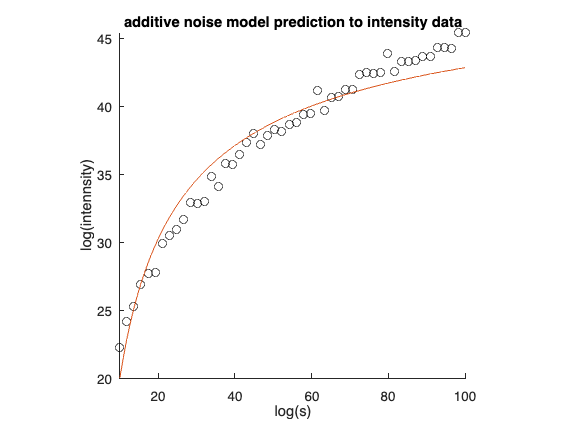


idx = find(r2 == max(r2));

f.perc_prm_additive = prm(idx, :);
f.perc_prd_additive = mkPercept_additive(f.thresh_axis, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), f.perc_prm_additive(1), f.perc_prm_additive(2), f.perc_prm_additive(3));

figure (2), clf
plot(s, f.intensity_dt, 'ko'), hold on
plot(f.thresh_axis, f.perc_prd_additive), title('additive noise model prediction to intensity data'), axis square, box off
xlabel('log(s)'), ylabel('log(intennsity)')

## Multiplicative model

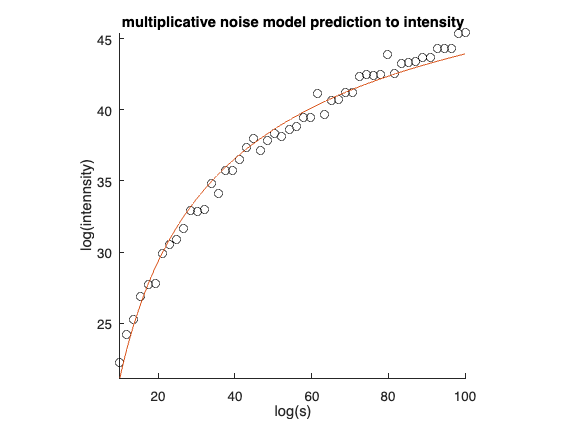

loss3 = @(s, d, w, beta, c, g, sc, dt) sum((log(mkPercept_multiplicative(s, d, w, beta, c, g, sc)) - log(dt)).^2);


% init = [1, 0.1, .8];

prm = []; prd = []; r2 = [];

for k = 1 : n_repeats
    init = rand(1, 3) * 10;

    prm(k, :) = fminsearch(@(x) loss3(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), x(1), x(2), x(3), f.intensity_dt), init);

    % make model predictions
    prd(k, :) = mkPercept_multiplicative(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), prm(1), prm(2), prm(3));

    % compute r2
    r2(k) = compute_r2(f.intensity_dt, prd(k, :));
end

idx = find(r2 == max(r2));

f.perc_prm_multiplicative = prm(idx, :);
f.perc_prd_multiplicative = mkPercept_multiplicative(f.thresh_axis, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), f.perc_prm_multiplicative(1), f.perc_prm_multiplicative(2), f.perc_prm_multiplicative(3));

figure (2), clf
plot(s, f.intensity_dt, 'ko'), hold on
plot(f.thresh_axis, f.perc_prd_multiplicative), title('multiplicative noise model prediction to intensity'), axis square, box off
xlabel('log(s)'), ylabel('log(intennsity)')

## Poisson model

loss4 = @(s, d, w, beta, c, sc, dt) sum((log(mkPercept_poisson(s, d, w, beta, c, sc)) - log(dt)).^2);


prm = []; prd = []; r2 = [];

for k = 1 : n_repeats
    init = rand(1, 2) * 10; % 10, 20

    prm(k, :) = fminsearch(@(x) loss4(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), x(1), x(2), f.intensity_dt), init);
    % make model predictions
    prd(k, :) = mkPercept_poisson(s, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), prm(1), prm(2));

    % compute r2
    r2(k) = compute_r2(f.intensity_dt, prd(k, :));
end

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.645582 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.593025 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.653720 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.624054 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.630877 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1.638554 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase 

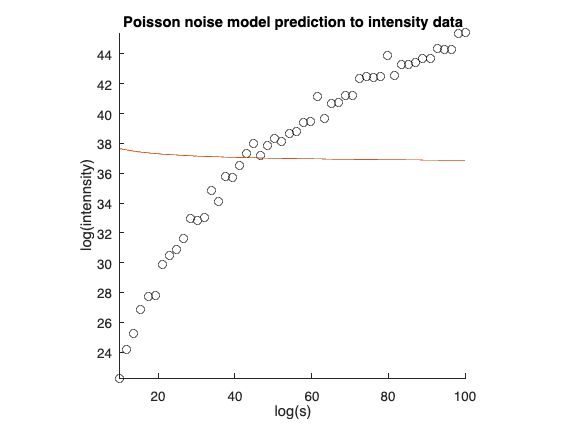


idx = find(r2 == max(r2));

f.perc_prm_poisson = prm(idx, :);
f.perc_prd_poisson = mkPercept_poisson(f.thresh_axis, f.thresh_prm(1), f.thresh_prm(2), f.thresh_prm(3), f.perc_prm_poisson(1), f.perc_prm_poisson(2));

figure (2), clf
plot(s, f.intensity_dt, 'ko'), hold on
plot(f.thresh_axis, f.perc_prd_poisson), title('Poisson noise model prediction to intensity data'), axis square, box off
xlabel('log(s)'), ylabel('log(intennsity)')

function output = mkPercept(s, d, w, beta, c, g, sc)

% s: stimulus, a vector
% d: the first constant from perceptual threshold fit
% w: the second constant from perceptual threshold fit
% beta: the third constant from perceptual threshold fit
% c: integration constant, to be fitted
% g: noise constant, to be fitted
% sc: scaling factor, to be fitted

step1 = w .* (d - s) + c .* (s - d).^beta;
step2 = g .* (s - d).^(-beta);
step3 = step1 .* step2 ./(2 * (beta - 1));
output = sinh(sc .* step3).^2./ g.^2;
end

% additive noise model ---------------------------------------
function output = mkPercept_additive(s, d, w, beta, sigma, c, sc)

% s: stimulus, a vector
% d, w, beta: constants from perceptual threshold fit
% sigma; standard deviation of the internal representation, to be fitted
% c: integration constant, to be fitted
% g: noise constant, to be fitted
% sc: scaling factor, to be fitted
step1 = w .* sigma .* (s - d).^(1-beta);
step2 = step1 ./(1-beta) + c;
output = sc .* step2;
end

% multiplicative noise model ---------------------------------

function output = mkPercept_multiplicative(s, d, w, beta, c, g, sc)

% all parameters are as stated in the previous two functions
step1 = g .* w .* (s - d).^(1-beta);
step2 = exp(step1 ./(1 - beta)) .* c;
output = sc .* step2;
end

% Poisson noise model ----------------------------------------

function output = mkPercept_poisson(s, d, w, beta, c, sc)

% all parameters are as previously stated
step1 = (w .* (d - s) + (beta - 1).* c .* (s - d).^beta) .^2;
step2 = (s - d).^(-2 .* beta) .* step1;
output = sc .* step2 ./ (4 .* (beta - 1).^2);
end

% compute r2 -------------------------------------------------
function r2 = compute_r2(data, prd)

r2 =  1 - (sum((data - prd).^2))./(sum((prd - mean(prd)).^2));

end